## Runga-Kutta Method 

## **Code: **

h=0.5; % step size
x = 0:h:10; % Calculates upto y(3)
Y = zeros(1,length(x));
%y(1) = [-0.5;0.3;0.2];
y(1) = 3; % redo with other choices here.
% initial condition
F_xy = @(t,y) (-2*y)+(3*exp(t)); % change the function as you desire
for i=1:(length(x)-1) % calculation loop
k_1 = F_xy(x(i),y(i));
k_2 = F_xy(x(i)+0.5*h,y(i)+0.5*h*k_1);
k_3 = F_xy((x(i)+0.5*h),(y(i)+0.5*h*k_2));
k_4 = F_xy((x(i)+h),(y(i)+k_3*h));
y(i+1) = y(i) + (1/6)*(k_1+2*k_2+2*k_3+k_4)*h; % main equation
end
% validate using a decent ODE integrator
tspan = [0,10]; y0 = -0.5;
[tx, yx] = ode45(F_xy, tspan, y0)

tx =          0
    0.0063
    0.0126
    0.0188
    0.0251
    0.0565
    0.0879
    0.1193
    0.1507
    0.2331


yx = 1.0e+04 *

   -0.0001
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000


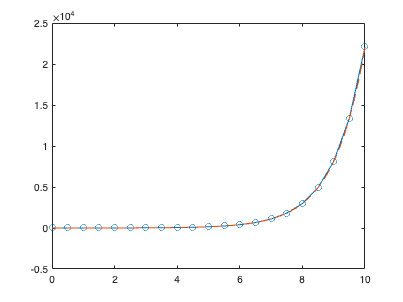


plot(x,y,'o-', tx, yx, '--')